## String Instrument Physical Modelling

### Digital Wave Guide

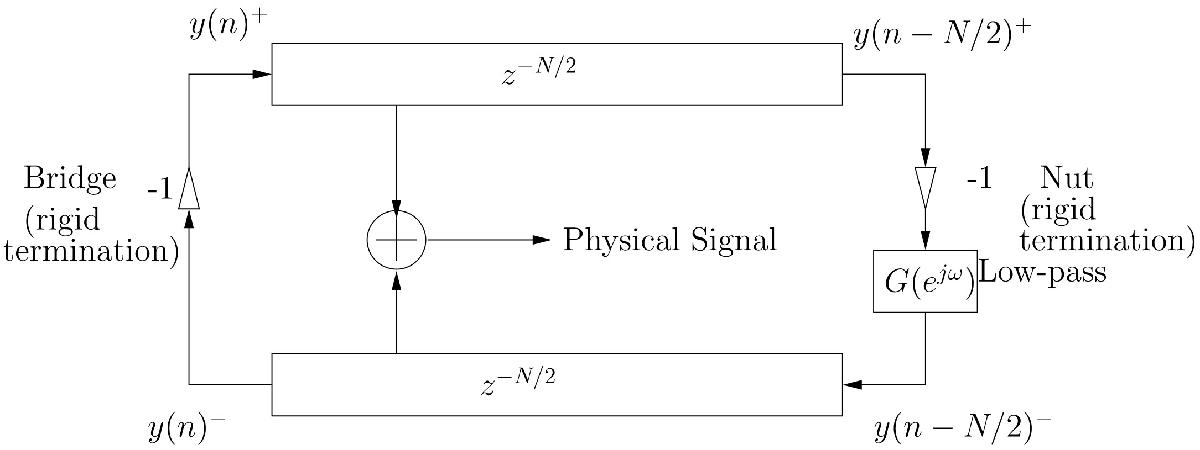


$$N=\frac{f_s }{f}$$


fs = 44100; % Sampling frequency
f = 440; % Freuency
N = round(fs/(2*f))+1;
mid = round(N/2);
t = 5; % Duration
tau = t/6.91;
ro = exp(-1/(f*tau))/cos(pi*f/fs);
N

N = 51

start_pos = 0; % Start position
pluck_pos = 26; % Pluck position
end_pos =  22; % End position
pick =  26; % Pick position
amp = 1; % Amplitude
init_shape = "triangle";
% Plucked string (violin): 0, 25, 51, 23, 0.25, t=0.4s, triangle
% Struck string (piano): 15, 25, 35, 10, 0.2 , t=5s, sine

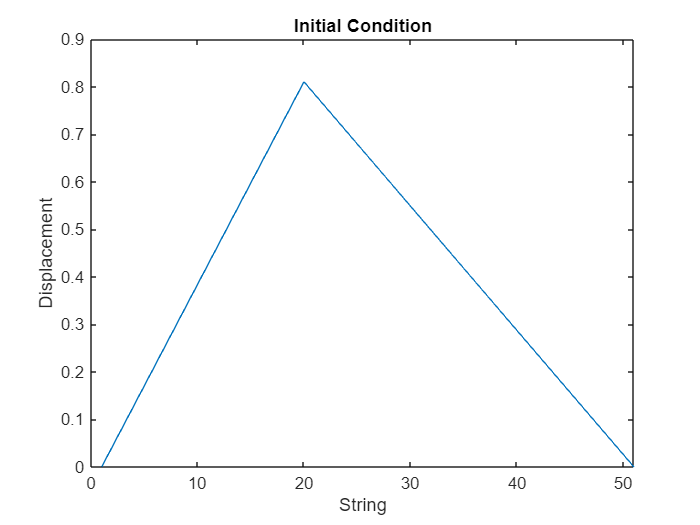

 

if init_shape == "triangle"
    down = linspace(1,0,end_pos-pluck_pos+1);
    initial = amp* [zeros(1,start_pos) linspace(0,1,pluck_pos-start_pos)... 
        down(2:end) zeros(1,N-end_pos)];
elseif init_shape == "box"
    initial = amp* [zeros(1,start_pos) ones(1,end_pos-start_pos) zeros(1,N-end_pos)];
elseif init_shape == "sine"
    initial = amp* [zeros(1,start_pos) sin(pi/(end_pos-start_pos) * [1:end_pos-start_pos]) zeros(1,N-end_pos)];
end
figure
plot(initial)
xlim([0,N])
xlabel('String')
ylabel('Displacement')
title('Initial Condition')

 

dline1 = initial;
dline2 = initial;

n = 5*fs; % 5s
y = zeros(1,n);

for i = 1:n
    y(i) = dline1(pick) + dline2(pick);
    for j = N-1:-1:1
        dline1(j+1) = dline1(j);
    end
    dline1(N) = ro*(1/2*dline1(N) + 1/2*dline1(N-1)); % low-pass filter
    for j = 1:N-1
        dline2(j) = dline2(j+1);
    end
    
    dline2(N) = -dline1(N);
    dline1(1) = -dline2(1);
end

soundsc(y,f*((N-1)*2-1/2))

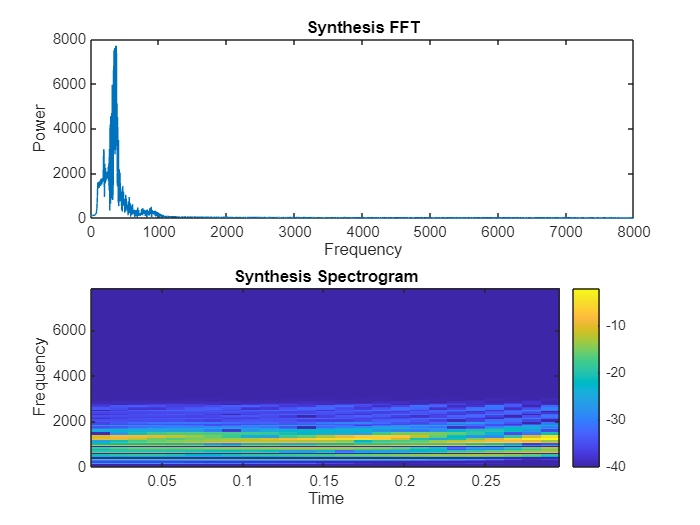

 

figure
subplot(2,1,1);
fn = [0:1/n:1-1/n]*fs;
plot(fn,abs(fft(y)))
xlim([0,8000])
title('Synthesis FFT')
xlabel('Frequency')
ylabel('Power')

subplot(2,1,2);
window = 1024;
[S,fc,t1] = melSpectrogram(y',fs, ...
                   "Window",hann(window,'periodic'),...
                   "OverlapLength",window/2,...
                   'NumBands',128, ...
                   'FrequencyRange',[0,8000]);
S = 10*log10(S+0.0001);
imagesc(t1, fc, S)
set(gca, 'YDir', 'normal'); % flip the Y Axis so lower frequencies are at the bottom
title('Synthesis Spectrogram')
xlabel('Time')
ylabel('Frequency')
colorbar

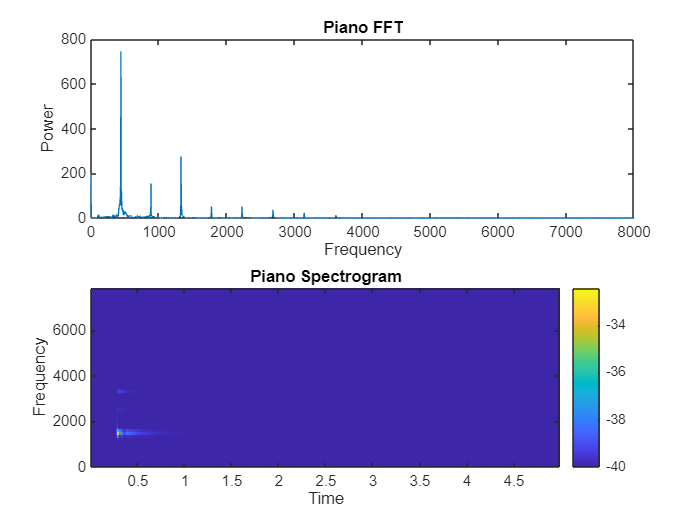

  % struck string

[piano,fs] = audioread('piano.ff.A4.aiff');
piano = piano(1:5*fs,1);
soundsc(piano,fs)
fn = [0:1/length(piano):1-1/length(piano)]*fs;

figure
subplot(2,1,1);
plot(fn,abs(fft(piano)))
xlim([0,8000])
title('Piano FFT')
xlabel('Frequency')
ylabel('Power')
subplot(2,1,2);
window = 1024;
[S,fc,t1] = melSpectrogram(piano,fs, ...
                   "Window",hann(window,'periodic'),...
                   "OverlapLength",window/2,...
                   'NumBands',128, ...
                   'FrequencyRange',[0,8000]);
S = 10*log10(S+0.0001);
imagesc(t1, fc, S);
set(gca, 'YDir', 'normal'); % flip the Y Axis so lower frequencies are at the bottom
title('Piano Spectrogram')
xlabel('Time')
ylabel('Frequency')
colorbar

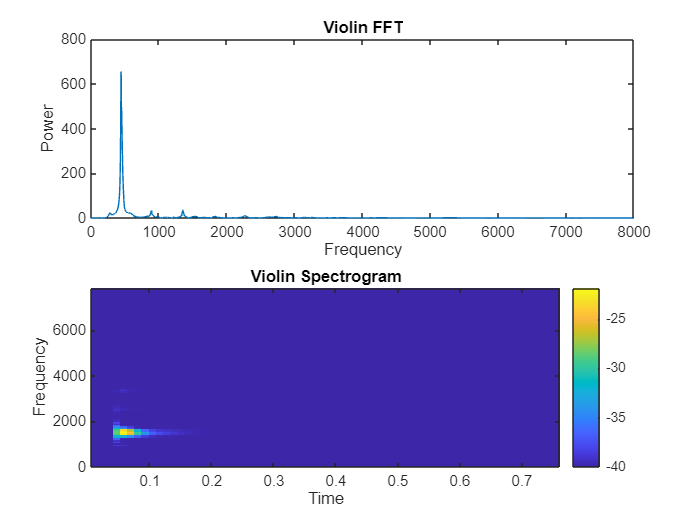

  % pizzicato; plucked string

[violin,fs] = audioread('Violin.pizz.ff.sulG.A4.stereo.aif');
violin = violin(:,1);
soundsc(violin,fs)

figure
subplot(2,1,1);
fn = [0:1/length(violin):1-1/length(violin)]*fs;
plot(fn,abs(fft(violin)))
xlim([0,8000])
title('Violin FFT')
xlabel('Frequency')
ylabel('Power')
subplot(2,1,2);
window = 1024;
[S,fc,t1] = melSpectrogram(violin,fs, ...
                   "Window",hann(window,'periodic'),...
                   "OverlapLength",window/2,...
                   'NumBands',128, ...
                   'FrequencyRange',[0,8000]);
S = 10*log10(S+0.0001);
imagesc(t1, fc, S);
set(gca, 'YDir', 'normal'); % flip the Y Axis so lower frequencies are at the bottom
title('Violin Spectrogram')
xlabel('Time')
ylabel('Frequency')
colorbar